## **AERO40003 Computing and Numerical Methods 1**

## **Coursework Project Part 2**

## ** 2021-2022**

## **Dr. Elnaz Naghibi**

## **Due Date: 25 March 2022**

### **Question 1 [5%]**

Plot the function $f\left(x\right)=\cos \;x\;\left(e^{2x} -2e^x +1\right)$ in the interval $\left\lbrack -\pi /4,3\pi /4\right\rbrack$ and find its two roots in the mentioned interval using MATLAB functions.

Using the derivative of the function and appropriate initial guesses from the plot of the function, verify which root can be found by fixed-point method. Use the fixed-point method to approximate this root and use the Secant method to find the other root (for which the fixed-point method does not work). Show the convergence to each root using appropriate plots and provide the codes for both methods.  Consider the tolerance value to be equal to 1e-6.

**Answer:**

You can use this space to explain the answers and include equations as needed using either Latex code or the live script equation editor from the tab "insert".

% Use this box for coding. 
% Outputs and graphs will be displayed on the right panel.
% To avoid submitting multiple files, please include functions at the bottom of your scripts.
format long g
f = @(x) (cos(x)).*(exp(2.*x)-2.*exp(x)+1);
x = linspace(-pi/4,3*pi/4,1000000);
y = f(x);
xint1 = [0 0.5];
xint2 = [1 2];
x1 = fzero(f,xint1);
x2 = fzero(f,xint2);
ans = [x1,x2]

ans =          0    1.5708


%Derivative of f is -(exp(x)-1)((exp(x)-1)sin(x)-2exp(x)cos(x))
fd = @(x) -(exp(x)-1).*((exp(x)-1).*sin(x)-2.*exp(x).*cos(x));
yd = fd(x);
xd1 = fd(x1) 

xd1 = 0

xd2 = fd(x2)

xd2 = -14.5197

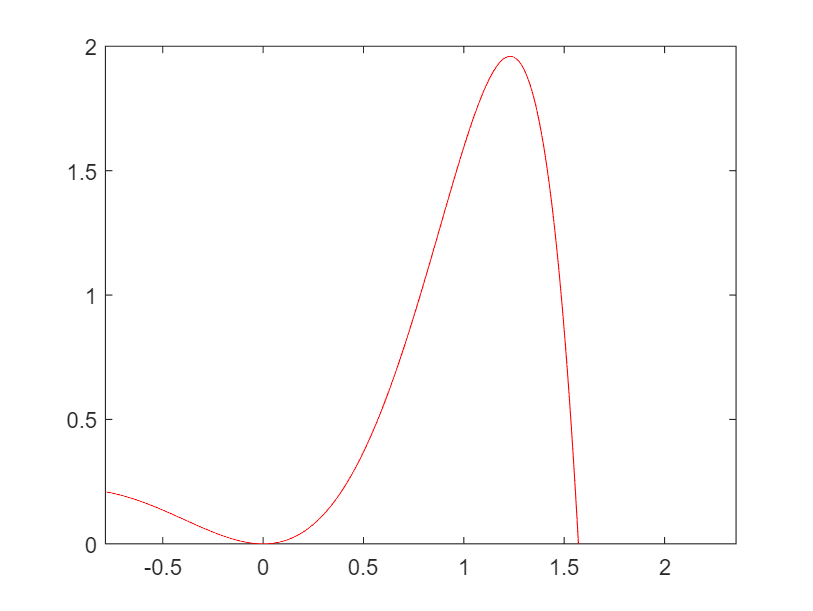

%Since derivative at root x1 is zero, the first root can be found via
%the fixed point method, however the root x2 cannot be found via this
%method
plot(x,y,'r-')
hold on
axis([-pi/4 3*pi/4 0 2]);
hold off

%To rearrange in terms of x, add x to both sides to have an equation in
%terms of x, i.e. x_n+1 = x_n + cos(x_n)*(e^(2x_n) - 2e^(x_n) + 1)
%It can therefore be concluded that only the root close to 0 can be found
%via the fixed point method as confirmed below
%eps = 1e-5;
%xi(1) = 1.8; %Change this value to TRY and obtain other root
%xi(2) = xi(1) + (cos(xi(1)))*(exp(2*xi(1))-2*exp(xi(1))+1)

xi =     1.8000   -3.9934


%i = 2;
%while (abs(x(i) - x(i-1))) > eps
%    xi(i+1) = xi(i) - (cos(xi(i)))*(exp(2*xi(i))-2*exp(xi(i))+1);
%    i = i + 1;
%end
%disp(x(i-1))

        -0.785398163397448



%Trying fixed point method again
x0 = input('Enter initial guess: ')

x0 =                       1.57


n = input('Enter number of times you want to iterate: ')

n =     10


eps = input('Enter your tolerance value: ')

eps =                      1e-05



i = 1;
while i <= n 
    x = f(x0);
    if abs(x-x0) < eps
        break
    else 
        i = i + 1;
        x0 = x; 
    end
end
disp(x)

      2.22044604925031e-16



%Works for root x1, root converges to 0 [correct value for x0]
%Doesn't work for other root x2, root still converges to 0

%Using the secant method, we can compute our x value without having to
%evaluate a derivative at x_n and instead use a finite difference approach
%i.e. x_n+1 = x_n - f(x_n)*((x_n - x_n-1)/(f(x_n) - f(x_n-1))
format long g 
n = 10000;
x(1) = 1.53;
x(2) = 1.63; 
for i = 2:n
    x(i+1) = x(i) - (f(x(i))*((x(i)-x(i-1))/(f(x(i)-f(x(i-1))))));
end
disp(x(i-1))

           1.6841933896318



%Secant method used here to compute root x2 which couldn't be found via
%the fixed point method

### **Question 2 [10%]**

**Part a: [5 %]**

Calculate Legendre polynomial of degree 6 using equation 16 in Handout_4 and MATLAB symbolic toolbox. Compare your resulting polynomial with "legendreP" function in MATLAB. Plot this function in the interval $\left\lbrack -1\ldotp 1\right\rbrack$ and calculate its roots $\eta_i$. Calculate weighting coefficients $w_i$ using the definition in equation 21. Using  $\eta_i$ and $w_i$, calculate the integral of  $\int_{-2}^1 \left({\textrm{ax}}^{10} +{\textrm{bx}}^5 +{\textrm{cx}}^2 \right)\;\textrm{dx}$ for arbitrary values of $a,b,c$ and show that it will be the same as its analytical value.

**Answer:**

%Equation 16 is L_N(x) = (1/(2^N * N!)) * diff((x^2-1)^N)
%Legendre Polynomial Code
N = 6;
syms b
coeff = 1/(2^N * factorial(N));
N_Df = diff(((b^2 - 1)^N),N);
LP_mine = N_Df * coeff; %output printed to the right 

% Compute simplified symbolic expression
simplifiedExpr = expand(LP_mine)

$$simplifiedExpr = \frac{231\,b^{6}}{16}-\frac{315\,b^{4}}{16}+\frac{105\,b^{2}}{16}-\frac{5}{16}$$

syms a
LP_check = legendreP(N,a)

$$LP\_check = \frac{231\,a^{6}}{16}-\frac{315\,a^{4}}{16}+\frac{105\,a^{2}}{16}-\frac{5}{16}$$

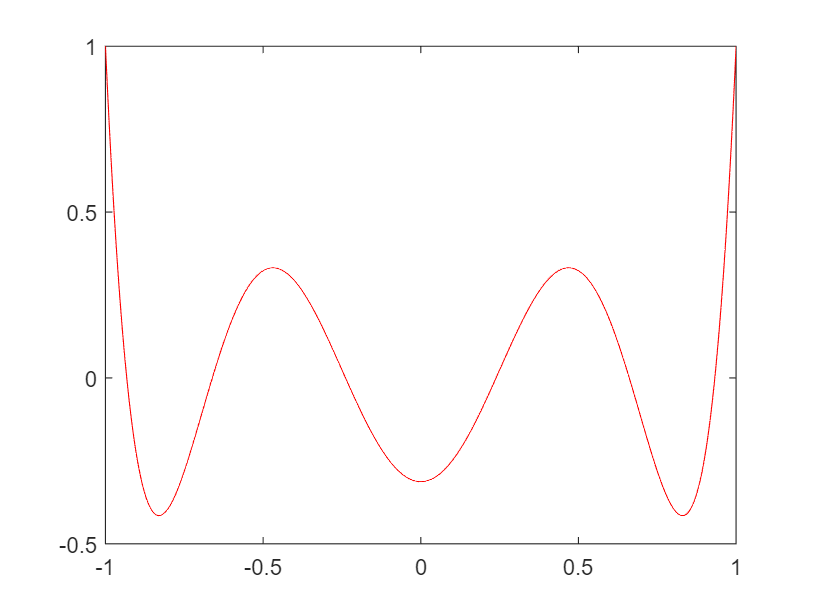

%After checking with MATLAB built-in, can see that both match
%Legendre polynomial of degree 6 is (1/16)*(231x^6 - 315x^4 + 105x^2 - 5)
xP = linspace(-1,1,1000000);
LP = @(x) (1/16)*(231*x.^6 - 315*x.^4 + 105*x.^2 - 5);
yP = LP(xP);
plot(xP,yP,'r-')

p = [231/16 0 -315/16 0 105/16 0 -5/16];
eta = roots(p);
eta = eta'

eta =    -0.9325   -0.6612    0.9325    0.6612   -0.2386    0.2386


syms x
LPDiff = diff(LP,x)

$$LPDiff = \frac{693\,x^{5}}{8}-\frac{315\,x^{3}}{4}+\frac{105\,x}{8}$$

LPD = @(x) (693*x.^5 - 630*x.^3 + 105*x)*(1/8)

LPD = function_handle with value:
    @(x)(693*x.^5-630*x.^3+105*x)*(1/8)


for val = 1:N
    w(val) = (2/(1-(eta(val))^2)) * (LPD(eta(val)))^(-2);
end
disp(w)

         0.171324492379167         0.360761573048138         0.171324492379171          0.36076157304814         0.467913934572691         0.467913934572691



%Integral is given by the summation of N values of w_N * f(eta_N)
%We want to compute the integral of a general polynomial; 
% a*x^10 + b*x^5 + c*x^2 between the limits of -2 and 1. We therefore
% require a change of variables
a = 1

a =      1


b = -5

b =     -5


c = 3

c =      3


lb = -2

lb =     -2


ub = 1

ub =      1


%New function needs to be determined using new variable, t %This bit needs
%to be FIXED
func = @(t) (((lb+ub)/2)*t + ((ub-lb)/2))*((ub-lb)/2)

func = function_handle with value:
    @(t)(((lb+ub)/2)*t+((ub-lb)/2))*((ub-lb)/2)


for c = 1:N
    LGI(c) = w(c)*func(eta(c));
end
LGI = sum(LGI)

LGI =           4.49999999999999


integral(@(x) a*x.^10 + b*x.^5 + c*x.^2,-2,1)

ans =           256.772727272727


**Part b: [5 %]**

Use Simpson integration scheme to calculate the below integral for $n=10,20,40,80$. Compare the results with the analytical value and calculate the error in each case. Plot error values versus $n$ and comment on the order of accuaracy of Simpson scheme. Provide the code for the integration and error calculation.


$$\int_0^{\frac{3\pi }{2}} \mathrm{x}\;\textrm{sinx}\;\textrm{dx}$$


**Answer:**

f = @(x) x.*sin(x);
n = input('Enter value for number of points between p and q: ')

n =      1000000


p = 0;
q = 3*pi/2;
x = linspace(p,q,n);
h = (x(2)-x(1));
coeffs = []


coeffs =

     []



for i = 2:2:n-1
    coeffs(i) = 4;
end
for i = 3:2:n-1
    coeffs(i) = 2;
end
coeffs(1) = 1;
coeffs(n) = 1;
y = f(x);
SI = (h/3)*sum((coeffs.*y))

SI =         -0.999992597792997


%Value for [10, 20, 40, 80] = [-0.225182, -0.620758, -0.812639, -0.906895]
ActI = integral(f,0,3*pi/2)

ActI =         -0.999999999999999


P_error = abs((SI-ActI)/ActI) * 100     

P_error =       0.000740220700223837


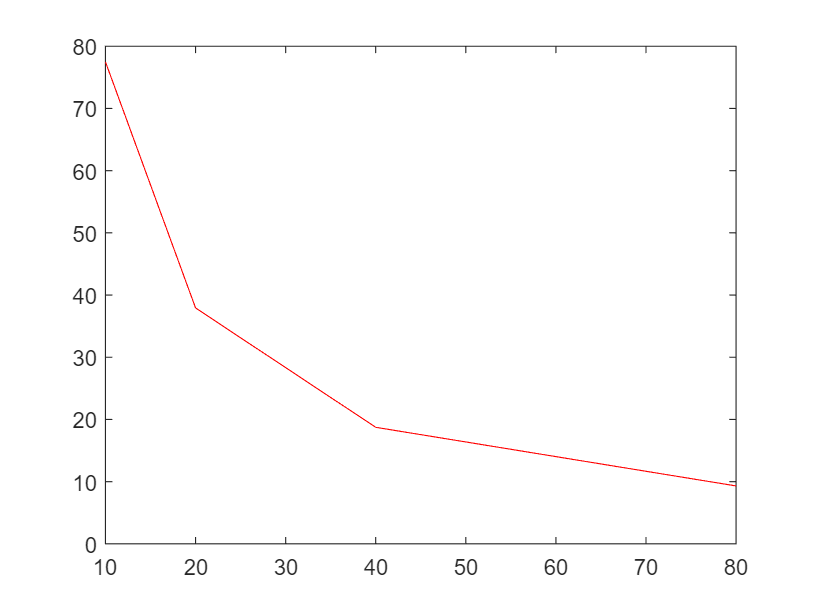

%P_error value for [10 20 40 80] = [77.4818, 37.9242, 18.7361, 9.3105]
n_val = [10 20 40 80];
P_error_val = [77.4818, 37.9242, 18.7361, 9.3105];
plot(n_val,P_error_val,'r-')

%The order of accuracy of the simpson scheme increases exponentially
%everytime the value of n is increased and is tending to zero percentage
%error.

### **Question 3 [10%]**

**Part a: [5%]**

Use Chebyshev distribution to sample 5 values of function $f\left(x\right)=\frac{1}{\cosh \;x}$ in the interval $\left\lbrack -0\ldotp 5,0\ldotp 5\right\rbrack$. Write a code to calculate the Lagrange interpolating polynomial passing though these points. Increase the number of points to 15 and rebuild the polynomial. Provide graphs to compare the original function and the interpolating polynomial and report the Euclidean norm of error in each case. 

**Answer:**

chebyshevT(5,x)

$$ans = 16\,x^{5}-20\,x^{3}+5\,x$$

chebyshevT(15,x)

$$ans = 16384\,x^{15}-61440\,x^{13}+92160\,x^{11}-70400\,x^{9}+28800\,x^{7}-6048\,x^{5}+560\,x^{3}-15\,x$$

**Part b: [5%]**

Use 9 equally spaced sample points for the function in part a and find the cubic splines passing through these points. Calculate the Euclidean norm of the error in this case and provide a graph to compare the original function and the cubic splines.

**Answer:**